# INTERPOLACIÓ POLINOMIAL

# Introduccio

p=[1 4 1 0]                   % vector amb els coeficients del polinomi 

p =      1     4     1     0


roots(p)                      % arrels

ans =          0
   -3.7321
   -0.2679


p=[1 0 0 0 0 -1]              % vector amb els coeficients del polinomi 

p =      1     0     0     0     0    -1


polyval(p,2)                  % valor polinomi

ans = 31

# Polinomi interpolador

La rutina polyinterp.m s'obtenen els valors del polinomi interpolador a la taula [x;y] i permet fer **la seva representació gràfica.** En cap cas obtenim els coeficients del polinomi interpolador. 

x = 1:6

x =      1     2     3     4     5     6


y = [16 18 21 17 15 12];
disp([x; y]);

     1     2     3     4     5     6
    16    18    21    17    15    12



polyinterp(x,y,4.5)

ans = 15.3164

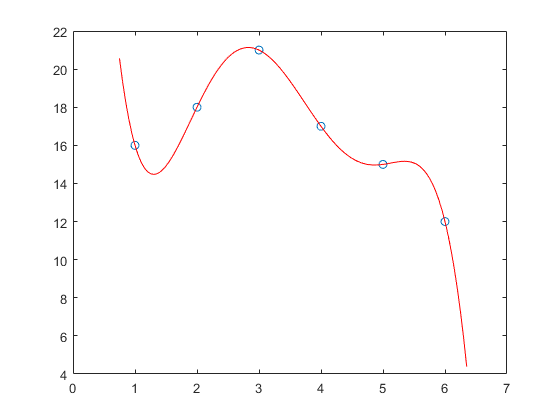

u = .75:0.05:6.35;
v = polyinterp(x,y,u);
plot(x,y,'o',u,v,'r-');

Els coeficients del polinomi interpolador es poden obtenir amb polifit, i els valors aproximats amb polyval. 

polyinterp de Moler = polyfit+polyval

x = 1:6

x =      1     2     3     4     5     6


y = [16 18 21 17 15 12];
disp([x; y]);

     1     2     3     4     5     6
    16    18    21    17    15    12



grau = length(x)-1;
p = polyfit(x,y,grau)

p =    -0.2417    4.3333  -28.9583   87.6667 -115.8000   69.0000


polyval(p,4.5)

ans = 15.3164

**Canvi de escala polinomi interpolador**

x = [0 .1 .4 .5 .6 1 1.4 1.5 1.6 1.9 2.0]

x =          0    0.1000    0.4000    0.5000    0.6000    1.0000    1.4000    1.5000    1.6000    1.9000    2.0000


y = [0 0.06 .17 .19 .21 .26 .29 .29 .39 .31 .31]

y =          0    0.0600    0.1700    0.1900    0.2100    0.2600    0.2900    0.2900    0.3900    0.3100    0.3100


[p, ~, mu] = polyfit(x,y,grau)

p =    -0.0202   -0.0463    0.0586    0.0381    0.0687    0.2501


mu =     1.0000
    0.7183


f = polyval(p,4.5,[], mu)

f = -73.2767

## Fenòmen de Runge

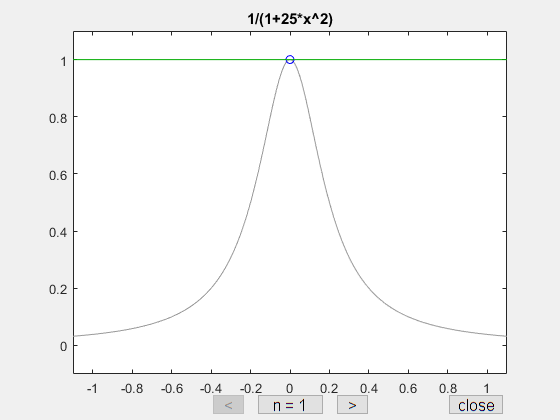

rungeinterp()

### Elecció optima de nodes

#### Abscisses de Chebyshev

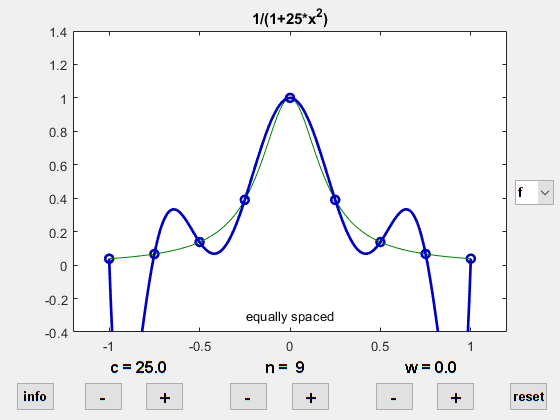

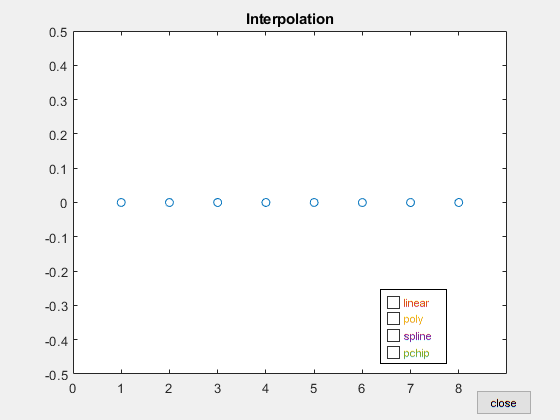

interp_gadget()

# Interpolació polinomial a trossos

## Linear Spline

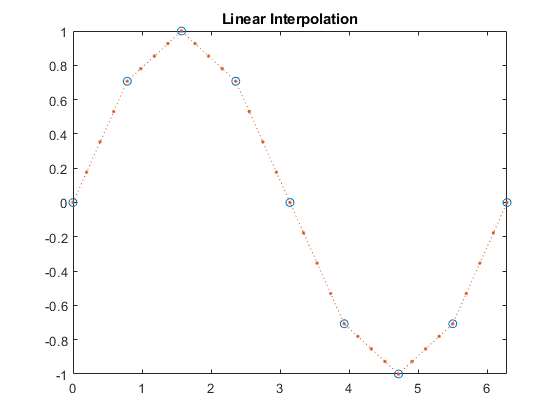

x = 0:pi/4:2*pi; 
v = sin(x);
xq = 0:pi/16:2*pi;
figure
vq1 = interp1(x,v,xq, 'linear');
plot(x,v,'o',xq,vq1,':.');
xlim([0 2*pi]);
title('Linear Interpolation');

## Spline Cúbic

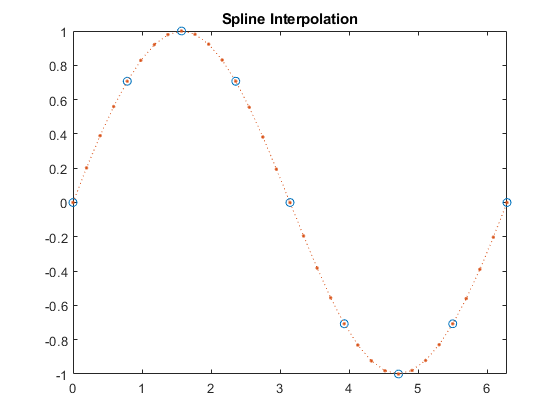

figure
vq2 = interp1(x,v,xq,'spline');
plot(x,v,'o',xq,vq2,':.');
xlim([0 2*pi]);
title('Spline Interpolation');

## Others

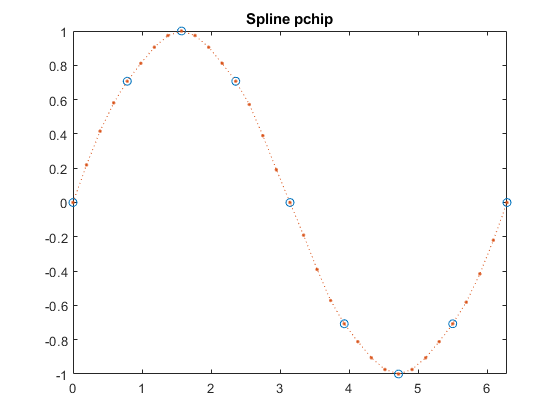

figure
vq2 = interp1(x,v,xq,'pchip');
plot(x,v,'o',xq,vq2,':.');
xlim([0 2*pi]);
title('Spline pchip');

figure
vq2 = interp1(x,v,xq,'linear','extrap')

vq2 =          0    0.1768    0.3536    0.5303    0.7071    0.7803    0.8536    0.9268    1.0000    0.9268    0.8536    0.7803    0.7071    0.5303    0.3536    0.1768    0.0000   -0.1768   -0.3536   -0.5303   -0.7071   -0.7803   -0.8536   -0.9268   -1.0000   -0.9268   -0.8536   -0.7803   -0.7071   -0.5303   -0.3536   -0.1768   -0.0000


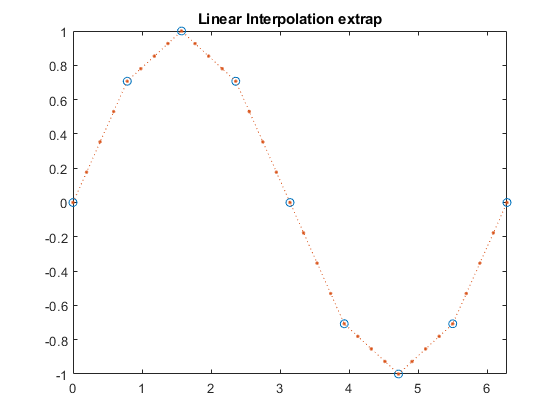

plot(x,v,'o',xq,vq2,':.');
xlim([0 2*pi]);
title('Linear Interpolation extrap');

# Ajust de dades

## Mètode dels mínims quadrats

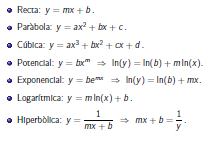

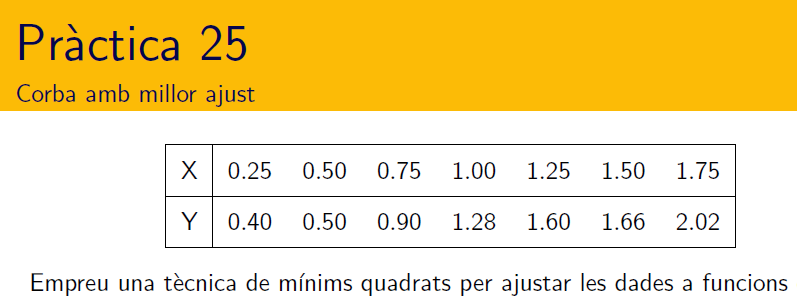

x = [0.25 0.50 0.75 1 1.25 1.50 1.75];
y = [0.40 0.50 0.90 1.28 1.60 1.66 2.02];
unos = ones(size(x));

**Recta**

A = [x' unos'];
b = y';
[l] = minimos_cuadrados(A,b);
m = l(1)

m = 1.1257

b = l(2)

b = 0.0686

**Parabola**

A = [x'.^2 x' unos'];
b = y';
[l] = minimos_cuadrados(A,b);
a = l(1)

a = -0.0990

b = l(2)

b = 1.3238

c = l(3)

c = -0.0057

**Cúbica**

**Potencial**

**Exponencial**

**Logarítmica**

**Hiperbòlica**

# Interpolació inversa

# 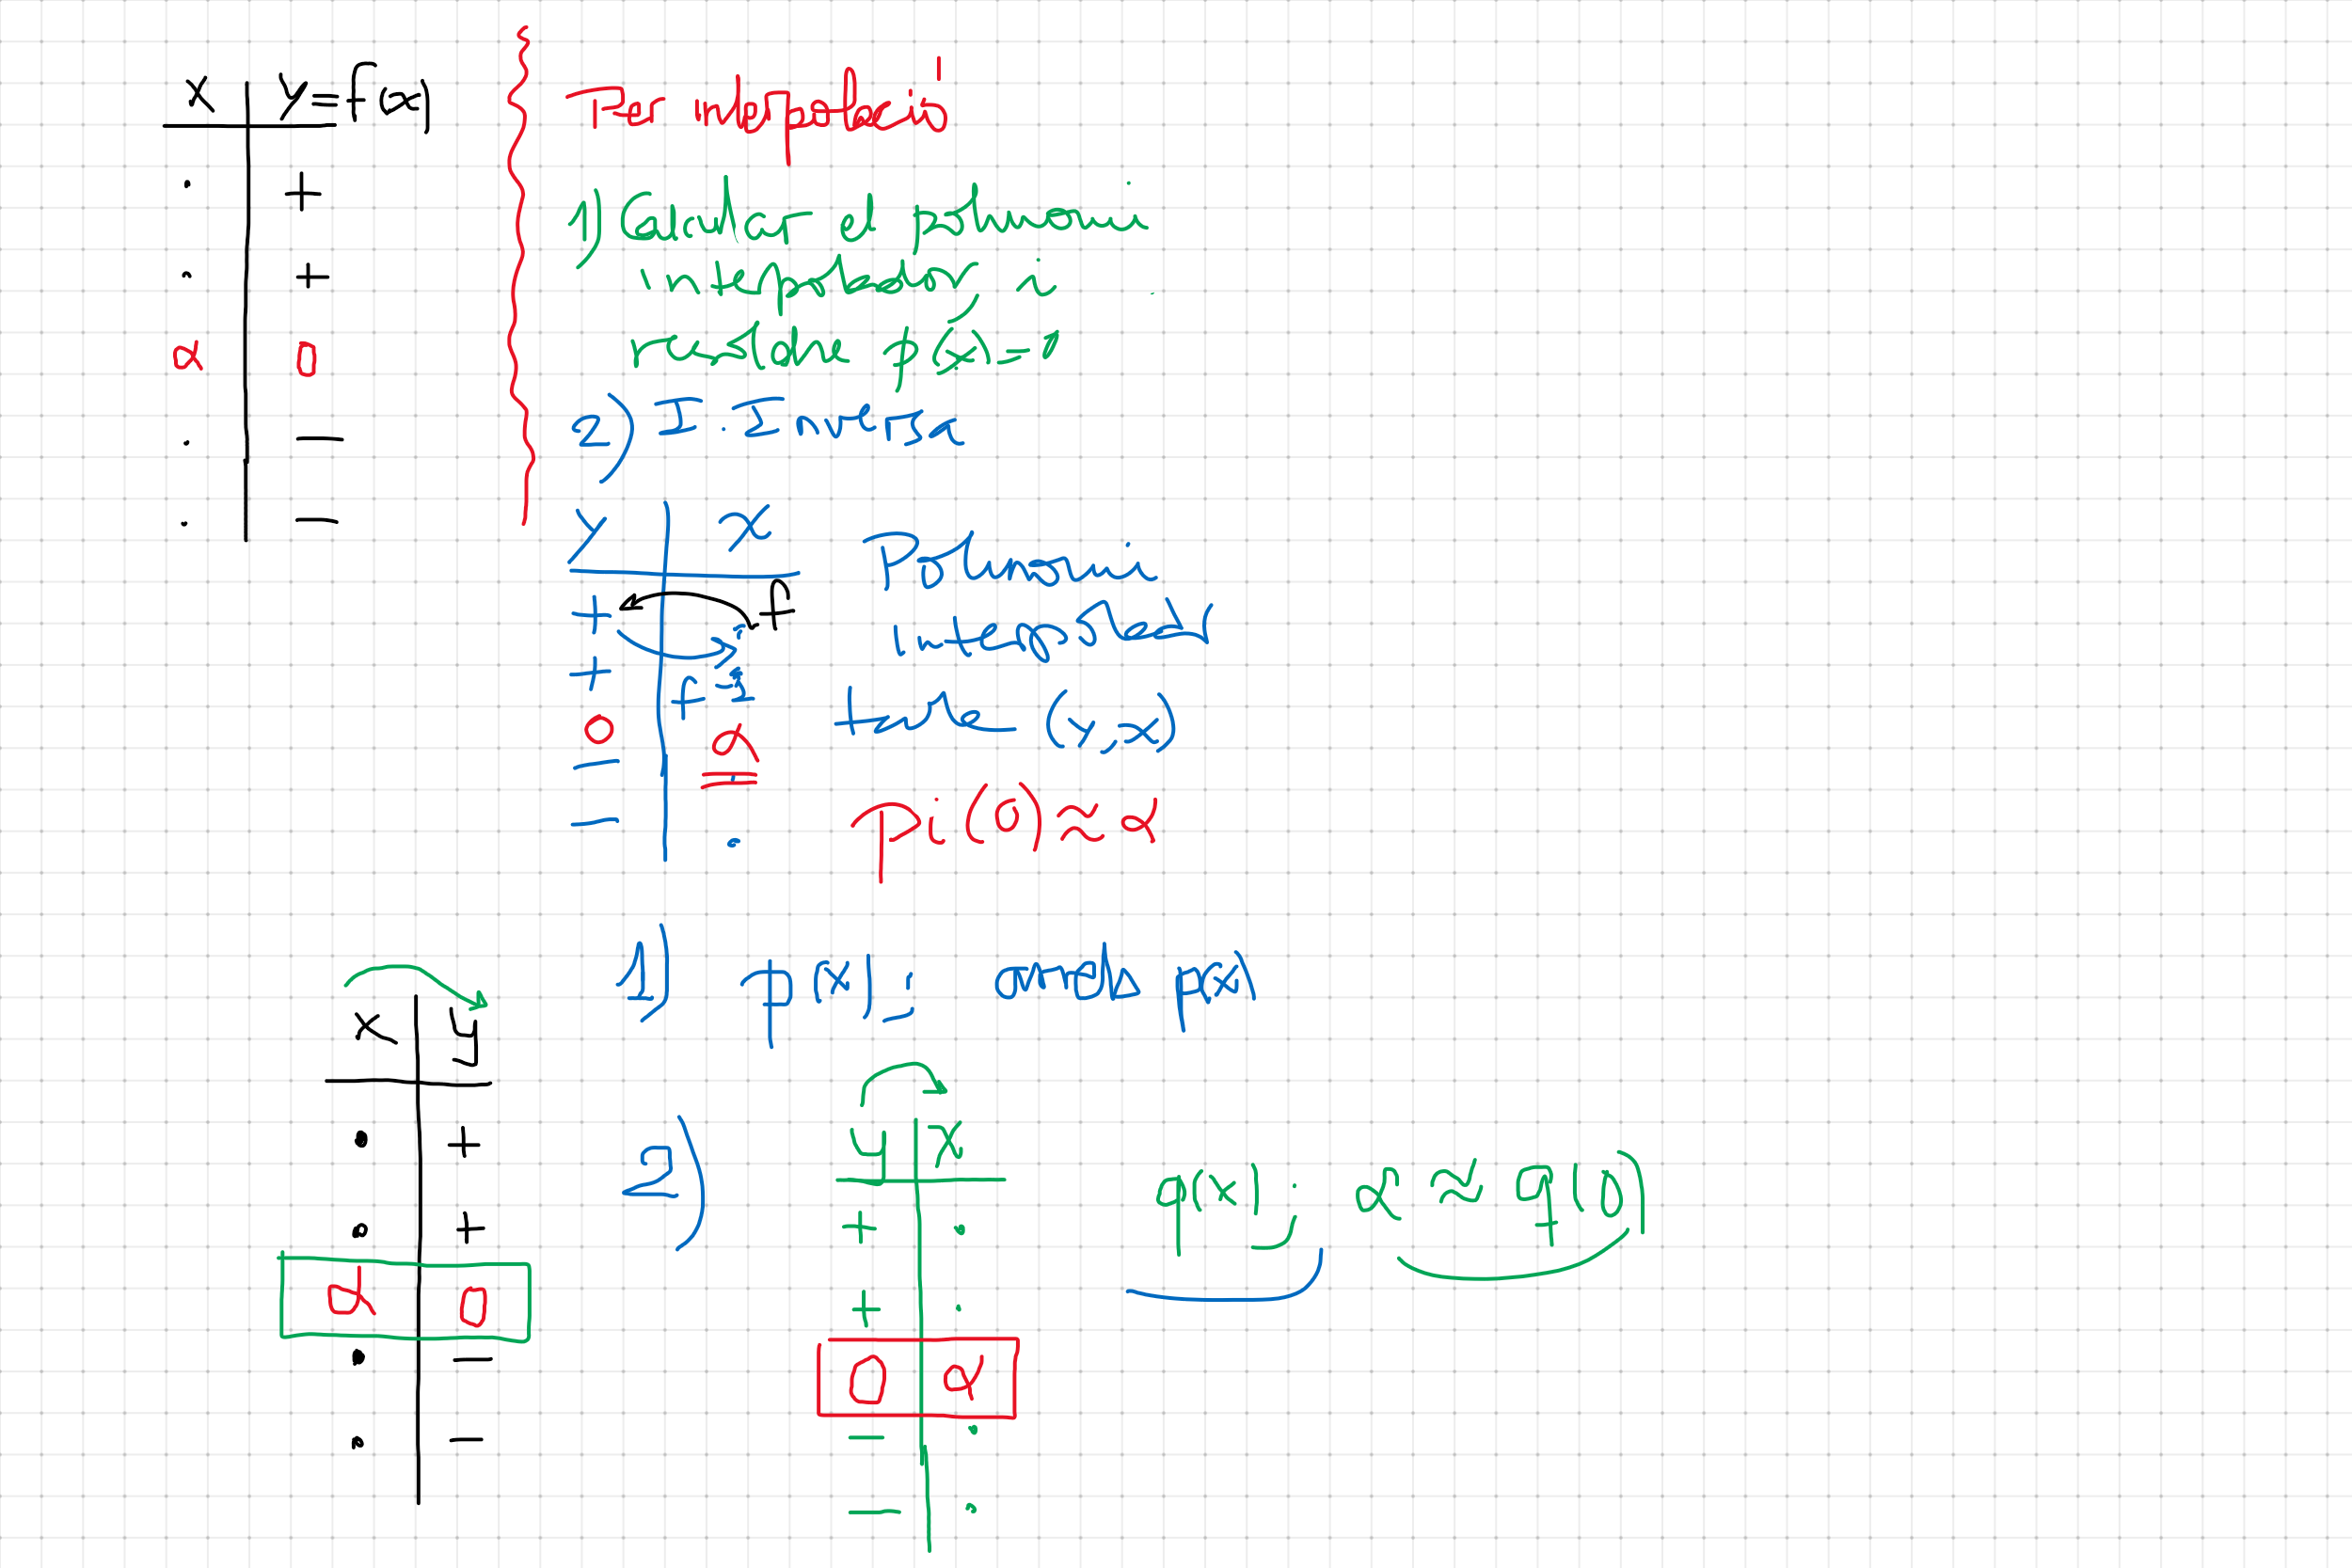

A =  [-0.5000   -0.2500   0.2500    0.5000    0.7500    1.0000    1.2500    1.5000;
      -1.3776   -1.2189  -0.7189   -0.3776    0.0183    0.4597    0.9347    1.4293];
xnodes = A(1,:)

xnodes =    -0.5000   -0.2500    0.2500    0.5000    0.7500    1.0000    1.2500    1.5000


ynodes = A(2,:)

ynodes =    -1.3776   -1.2189   -0.7189   -0.3776    0.0183    0.4597    0.9347    1.4293


alpha = polyinterp(ynodes,xnodes,0)

alpha = 0.7391

# Resum 

interpgui()

function [x] = minimos_cuadrados(A,b)
    %A'*Ax=A'b
    C = A'*A;
    d = A'*b;
    x = C\d;
end